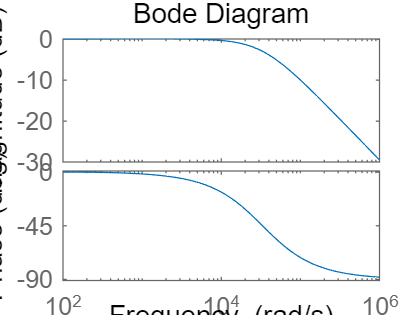

%% components value
L = 29.87e-6;
C = 3e-3;
Rc = 1;
Wc = 4/sqrt(L*C);
load = 8.533;

%% calculate Kmisc
alpha = 1/4;
Kpwm = 0.45/(3.8-0.3);  % dmax/(Vmax-Vmin)
Vso = 30*sqrt(2);   % or 30*sqrt(2) here?
n = 4/5;  % N2/N1
Kmisc = alpha*Kpwm*Vso*n;

%% output filter
Gf = tf([Rc*C,1], [L*C,(L/load+C*Rc),1]);
bode(Gf);

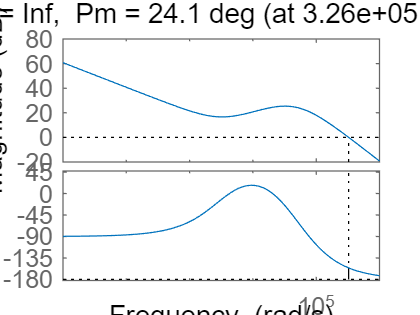


%% controller
B=-30-(-156); % degree, B should larger than 70 (<150)
k=[tan(deg2rad(B/4+45))]^2;
G=1/(Kmisc*10^(-23/20));
A=G*Wc/k;
Gc=tf(A,[1,0])*tf([k/Wc^2,2*sqrt(k)/Wc,1],[1/(k*Wc^2),2/(sqrt(k)*Wc),1]);

%% overall
overall_tf=Gc*Kmisc*Gf;
margin(overall_tf);


R1=1000;
